

load("intercluster_strength_data_A09threshold.mat")

%use git code multicat: https://github.com/GenLouvain/GenLouvain/blob/master/HelperFunctions/multiaspect.m
%multilayer modularity (categorical coupling)

gamma = 1;
omega = 1;


[B,twom] = multicat(A, gamma, omega);
[S,Q]= genlouvain(B);

Merging 64 communities  29-Mar-2023 12:54:48
5 change: 1771 total: 1771 relative: 1
5 change: 0 total: 1771 relative: 0
Merging 5 communities  29-Mar-2023 12:54:48
5 change: 0 total: 1771 relative: 0


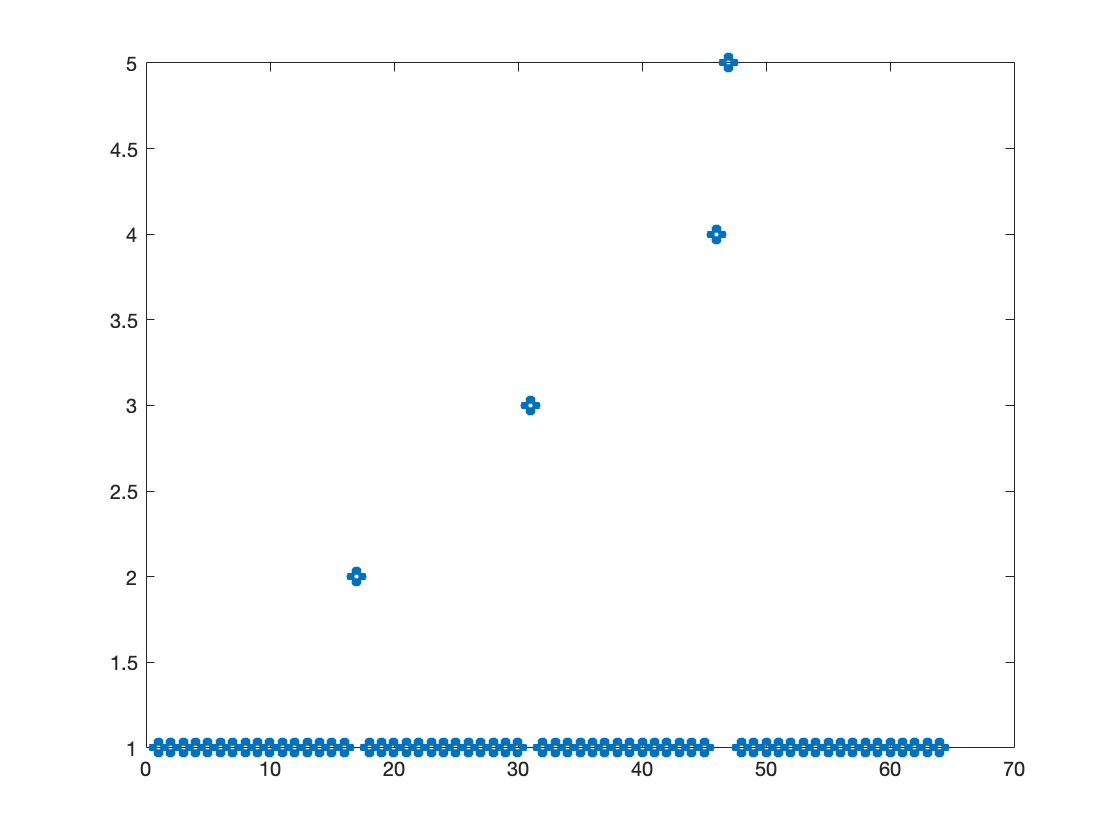

figure;
plot(S,'o','LineWidth',4);

%1 - everything else except below
%2 - 17
%3 - 31
%4 - 46
%5 - 47 

modularity_of_A = [];

for i=1:L
    [B,twom] = modularity(A(i),gamma);
    modularity_of_A = [modularity_of_A, {B}];
    %[S,Q]= genlouvain(B); 
    %fprintf("\nModularity %d",i)

end
